# 06 – Lineární časově invariantní soustavy (LTI)  

**Systém** představuje obecný popis prostředí, kterým prochází informace a je tímto prostředím ovlivňována. V signálovém zpracování se jedná o systém definovaný přenosem systému, který na vstupní signál $x\left\lbrack n\right\rbrack$ reaguje výstupním signálem $y\left\lbrack n\right\rbrack$ - **kauzálně**. LTI systémy lze charakterizovat **časovou invariancí**, tj. nemění své parametry s časem. Je **lineární**, platí v něm **principy superpozice**. Základní vlastností LTI systému je jeho popis pomocí přenosové funkce $H\left\lbrack f\right\rbrack$, kde modul (absolutní hodnota) reprezentuje útlum/zesílení jednotlivých harmonických složek procházejících systémem. Fáze reflektuje zpoždění frekvenčních složek na výstupu oproti vstupu. Z toho vyplývá, že **LTI systém mění spektrum signálu a způsobuje zpoždění**.

V časové oblasti se systém popisuje impulzní odezvou $h\left\lbrack n\right\rbrack$, tj. odpovědí (výstupem) systému na vstupující jednotkový impulz $\delta \left\lbrack n\right\rbrack$ (ve spojitém čase ideálním Diracovým impulsem). U diskrétních signálů je tedy jednotkový impulz zapsán jedničkou následovanou nulami. Spektrum $H\left\lbrack f\right\rbrack$ impulzní odezvy $h\left\lbrack n\right\rbrack$ odpovídá přenosové funkci $H\left\lbrack f\right\rbrack =\textrm{DFT}\left\lbrace h\left\lbrack n\right\rbrack \right\rbrace$.  Naopak, inverzní DFT získáme z přenosové funkce impulzní odezvu $h\left\lbrack n\right\rbrack =\textrm{IDFT}\left\lbrace H\left\lbrack f\right\rbrack \right\rbrace$.

Signál $y\left\lbrack n\right\rbrack$ (se spektrem $Y\left\lbrack f\right\rbrack$) považujme za výstup systému, do kterého vstupuje signál $x\left\lbrack n\right\rbrack$ (se spektrem $X\left\lbrack f\right\rbrack$). Vztah, mezi signálem na vstupu a výstupu můžeme zapisovat dvěma způsoby - v časové a frekvenční oblasti. Ve frekvenční oblasti se jedná o prosté skalární násobení spekter vstupbního signálu a přenosu systému:

Frekvenční oblast: $Y\left\lbrack f\right\rbrack =X\left\lbrack f\right\rbrack \cdot H\left\lbrack f\right\rbrack$

Skalární násobení ve spektru má v časové rovině obraz jako **konvoluce** signálů:

 Časová oblast: $y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack \ast h\left\lbrack n\right\rbrack$

**Konvoluce** (operátor $\ast$) je matematickou operací, která v reálném světě nemá fyzikální interpretaci (jedná se o "křížovou korelaci s v čase obrácenou impulzní odezvou"). Výpočetní náročnost konvoluce je $N^2$, tedy s délkou impulzní odezvy (složitostí systému) roste i výpočetní náročnost. V praxi se využívá implementace „konvolučního automatu“ výhodné pro např. digitální filtraci v reálném čase, ale principiálně lze využít i složitosti $N\;\log \;N$ve FFT obdobně, jako u korelační funkce.


$$x\left\lbrack n\right\rbrack \ast h\left\lbrack n\right\rbrack =\sum_{k=0}^{M-1} x\left\lbrack n-k\right\rbrack \cdot h\left\lbrack k\right\rbrack ;\;M\;\textrm{je}\;\textrm{délka}\;\textrm{impulzní}\;\textrm{odezvy}\ldotp$$


**Cíle:**

    **1) Identifikace systému:**

- **Načtěte neznámý systém (blackbox)**

- **Pomocí jednotkového impulzu získejte jeho impulzní odezvu**

- **Zobrazte modul a fázi přenosové funkce, určete typ systému (typ filtru)**

**    2) Konvoluce **

- **Načtěte signál EKG a spočtěte odhad PSD (Welchova metoda)**

- **Konvolvujte EKG signál s impulzní odezvou systému**

- **Výsledek zobrazte společně s odhadem PSD **

- **Popište výsledek konvoluce, změnu signálu a časové zpoždění**

**Užitečné funkce: **

## **Nápověda:**

### 1) Identifikace systému

Identifikujte přenosovou funkci $H\left\lbrack f\right\rbrack$ z impulzní odezvy $h\left\lbrack n\right\rbrack$ neznámého systému uloženého v šifrované funkci `blackbox_2021.p:`

Vygenerujte si jednotkový impulz $\delta \left\lbrack n\right\rbrack$ délky alespoň jedné sekundy.


$$\delta \left\lbrack n\right\rbrack =\left\lbrace \begin{array}{ll}
1 & n=1\\
0 & n>1
\end{array}\right.$$
 

fs=500; % vzorkovací kmitočet např. 500 Hz
d = zeros(1,fs);        % d=... jednotkový impulz [1 0 0 ...]  délky 1s (fs vzorků)
d(1) = 1 ;       
h = blackbox_2021(d,fs);% h=... impulzní odezva systému "h=blackbox_2021(d,fs)"

Spočtěte spektrum impulzní odezvy, tj. přenosovou funkci $H\left\lbrack f\right\rbrack =\textrm{DFT}\left\lbrace h\left\lbrack n\right\rbrack \right\rbrace$.

Pozn.: Spektrum výstupního signálu je výsledek násobení spektra vstupního signálu a přenosové funkce  $Y\left\lbrack f\right\rbrack =X\left\lbrack f\right\rbrack \cdot H\left\lbrack f\right\rbrack$. V dřívějších hodinách jsme po DFT (`fft`) prováděli normalizaci magnitudy spektra pro přímou interpretaci amplitudy harmonických složek a magnitudy spektrální čáry na straně frekvence $X\left\lbrack f\right\rbrack =\frac{1}{N}\textrm{DFT}\left\lbrace x\left\lbrack n\right\rbrack \right\rbrace$. Pokud celý proces přepíšeme jako $\textrm{DFT}\left\lbrace y\left\lbrack n\right\rbrack \right\rbrace =\frac{1}{N}\textrm{DFT}\left\lbrace x\left\lbrack n\right\rbrack \right\rbrace \cdot \textrm{DFT}\left\lbrace h\left\lbrack n\right\rbrack \right\rbrace$ je patrné, že normalizaci provedeme pouze u signálu, u přenosové funkce tedy **nenormalizujeme** $\frac{1}{N}$. 

Nezapomeňte vykreslit s odpovídající f osou.

H = fft(h)        % H... přenosová funkce fft() bez normalizace 1/N

H =    1.0000 + 0.0000i   0.3091 - 0.9512i  -0.8094 - 0.5881i  -0.8097 + 0.5883i   0.3094 + 0.9522i   1.0013 + 0.0000i   0.3094 - 0.9522i  -0.8097 - 0.5883i  -0.8094 + 0.5880i   0.3090 + 0.9512i   1.0000 + 0.0000i   0.3090 - 0.9512i  -0.8094 - 0.5881i  -0.8097 + 0.5883i   0.3094 + 0.9522i   1.0014 + 0.0000i   0.3094 - 0.9522i  -0.8097 - 0.5883i  -0.8094 + 0.5881i   0.3091 + 0.9512i   1.0000 - 0.0000i   0.3091 - 0.9512i  -0.8093 - 0.5880i  -0.8095 + 0.5882i   0.3093 + 0.9518i   1.0008 + 0.0000i   0.3093 - 0.9519i  -0.8100 - 0.5885i  -0.8105 + 0.5889i   0.3099 + 0.9538i   1.0035 + 0.0000i   0.3097 - 0.9532i  -0.8063 - 0.5858i  -0.7958 + 0.5782i   0.2966 + 0.9128i   0.9218 + 0.0000i   0.2680 - 0.8248i  -0.6436 - 0.4676i  -0.5728 + 0.4161i   0.1879 + 0.5784i   0.5014 - 0.0000i   0.1218 - 0.3750i  -0.2374 - 0.1725i  -0.1656 + 0.1203i   0.0408 + 0.1255i   0.0771 + 0.0000i   0.0121 - 0.0374i  -0.0129 - 0.0094i  -0.0027 + 0.0019i  -0.0008 - 0.0023i


f = linspace(0,fs-1/fs,fs);        % f... frekvenční osa
t = linspace(0,1-1/fs,fs);

Zobrazte jednotkový impulz `d`, odezvu systému `h`, přenosovou funkci systému `H` (absolutní i fázové):

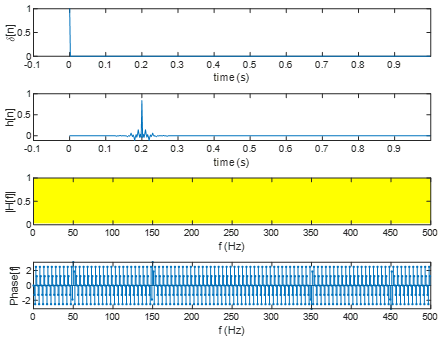  Pozn. žluté pole zakrývá řešení =)

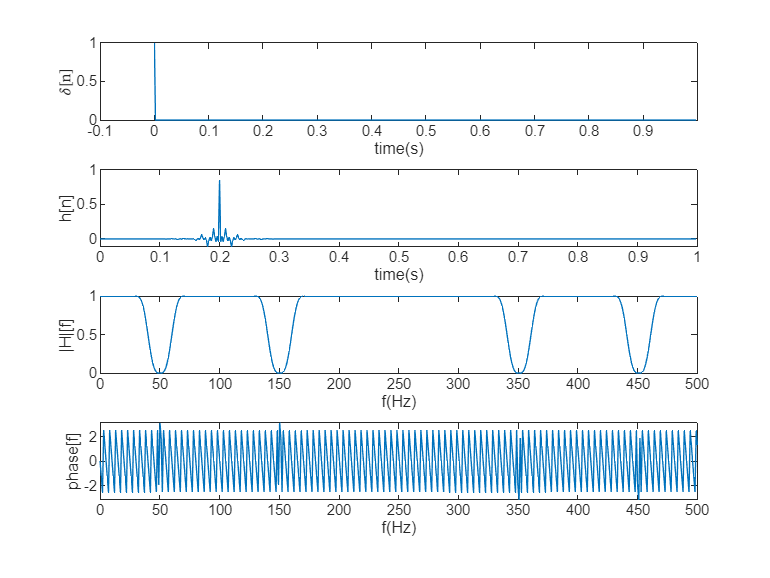

figure
subplot(4,1,1)
plot(t,d)
xlim([-0.1 1])
xlabel("time(s)")
ylabel('$\delta$[n]',Interpreter="latex")

subplot(4,1,2)
plot(t,h)
xlabel("time(s)")
ylabel('h[n]')

subplot(4,1,3)
plot(f, abs(H))
xlabel("f(Hz)")
ylabel("|H|[f]")

subplot(4,1,4)
plot(f,angle(H))
xlabel("f(Hz)")
ylabel("phase[f]")

Hdb = 20*log10(H)

Hdb =    0.0000 + 0.0000i   0.0011 -10.9150i   0.0040 -21.8300i   0.0076 +21.8300i   0.0104 +10.9150i   0.0116 + 0.0000i   0.0104 -10.9150i   0.0075 -21.8300i   0.0039 +21.8300i   0.0009 +10.9150i  -0.0002 + 0.0000i   0.0009 -10.9150i   0.0039 -21.8300i   0.0077 +21.8300i   0.0107 +10.9150i   0.0118 + 0.0000i   0.0107 -10.9150i   0.0077 -21.8300i   0.0041 +21.8300i   0.0013 +10.9150i   0.0002 - 0.0000i   0.0012 -10.9150i   0.0034 -21.8300i   0.0057 +21.8300i   0.0071 +10.9150i   0.0073 + 0.0000i   0.0076 -10.9150i   0.0101 -21.8300i   0.0162 +21.8300i   0.0250 +10.9150i   0.0304 + 0.0000i   0.0194 -10.9150i  -0.0289 -21.8300i  -0.1427 +21.8300i  -0.3562 +10.9150i  -0.7077 + 0.0000i  -1.2376 -10.9150i  -1.9873 -21.8300i  -2.9998 +21.8300i  -4.3197 +10.9150i  -5.9957 - 0.0000i  -8.0833 -10.9150i -10.6494 -21.8300i -13.7795 +21.8300i -17.5905 +10.9150i -22.2610 + 0.0000i -28.1138 -10.9150i -35.9465 -21.8300i -49.6480 +21.8300i -52.2496 -16.3725i


f(Hdb<-3)

ans =    39.0780   40.0800   41.0820   42.0840   43.0860   44.0880   45.0900   46.0920   47.0940   48.0960   49.0980   50.1000   51.1020   52.1040   53.1060   54.1080   55.1100   56.1120   57.1140   58.1160   59.1180   60.1200   61.1220  139.2780  140.2800  141.2820  142.2840  143.2860  144.2880  145.2900  146.2920  147.2940  148.2960  149.2980  150.3000  151.3020  152.3040  153.3060  154.3080  155.3100  156.3120  157.3140  158.3160  159.3180  160.3200  161.3220  339.6780  340.6800  341.6820  342.6840


**Dokončete:**

**Popište systém jako filtr (typ propusti, zádrže, mezní kmitočty apod.): ...**

 Jedná se o dvě pásmové zádrže na 50 a 150 Hz

Jaký je mezní kmitočet/kmitočty filtru, tj. frekvence, kde je útlum $|H\left\lbrack f\right\rbrack |=-3\;\textrm{dB}$: Pokud máte vykreslen modul přenosové funkce lineárně, převeďte -3dB do lineární míry.  


$$x_{\textrm{dB}} =20{\cdot \log }_{10} x$$
 


$$x={10}^{\frac{x_{\textrm{dB}} }{20}}$$
  

**Mezní kmitočet(y) filtru jsou... 39.1/61.1 Hz a 139.3/161.3 Hz**

### 2) Konvoluce

Proveďte konvoluci signálu s impulzní odezvou systému.

Načtěte EKG signál a zobrazte jeho odhad PSD Welchovou metodou. Konvolvujte ho s impulzní odezvou systému. **Pozor, impulzní odezva musí být zjištěna pro stejný vzorkovací kmitočet **$f_s$ **jako má signál! **Zobrazte výsledek konvoluce $y\left\lbrack n\right\rbrack =\textrm{ecg}\left\lbrack n\right\rbrack \ast h\left\lbrack n\right\rbrack$ a jeho odhad PSD pomocí Welchovy metody. Porovnejte výsledek konvoluce a výstupu systému `blackbox_2021(ecg,fs)`.

ecg=load('ecg_hum_fs500Hz.txt');
fs=500;
N = length(ecg);
t = linspace(0,(N-1)/fs,N);      % t=... časová osa
f = linspace(0,fs-fs/N,N)

f =          0    0.0667    0.1333    0.2000    0.2666    0.3333    0.3999    0.4666    0.5333    0.5999    0.6666    0.7332    0.7999    0.8666    0.9332    0.9999    1.0665    1.1332    1.1998    1.2665    1.3332    1.3998    1.4665    1.5331    1.5998    1.6664    1.7331    1.7998    1.8664    1.9331    1.9997    2.0664    2.1330    2.1997    2.2664    2.3330    2.3997    2.4663    2.5330    2.5997    2.6663    2.7330    2.7996    2.8663    2.9329    2.9996    3.0663    3.1329    3.1996    3.2662


d = zeros(1,fs);        % d=... jednotkový impulz [1 0 0 ...]  délky 1s (fs vzorků)
d(1) = 1 ;
h = blackbox_2021(d,fs);        % h=... impulzní odezva
ecg_f = conv(ecg,h,'full');        % ecg_f=... EKG konvoluce s impulzní odezvou h

Uvědomte si, že operace konvoluce na okrajích prodlouží signál délky $N$* o *délku impulzní odezvy $M-1$. Výsledek konvoluce tedy bude mít rozměr $N+M-1$.

Definujte časovou osu pro konvolvovaný (filtrovaný) signál:

N = N + length(h) - 1;
t_f = linspace(0,(N-1)/fs,N);        % t_f=... časová osa pro filtrovaný signál

Nechte projít původní EKG signál neznámým systémem a také jej zobrazte:

ecg_bbox=blackbox_2021(ecg,fs);

Odhadněte PSD Welchovou metodou pro původní signál, konvolvovaný signál a signál pro průchodu systémem:

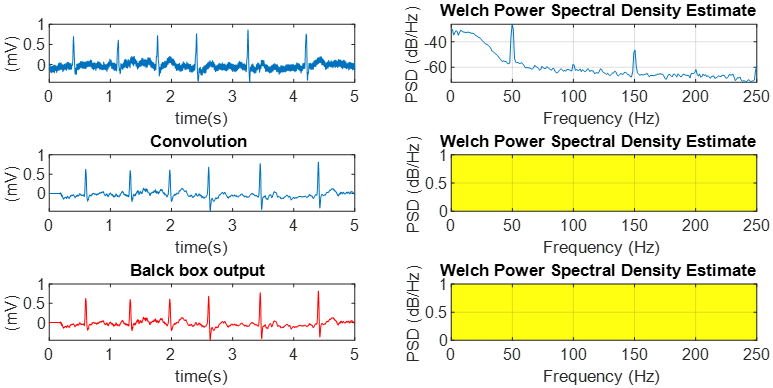

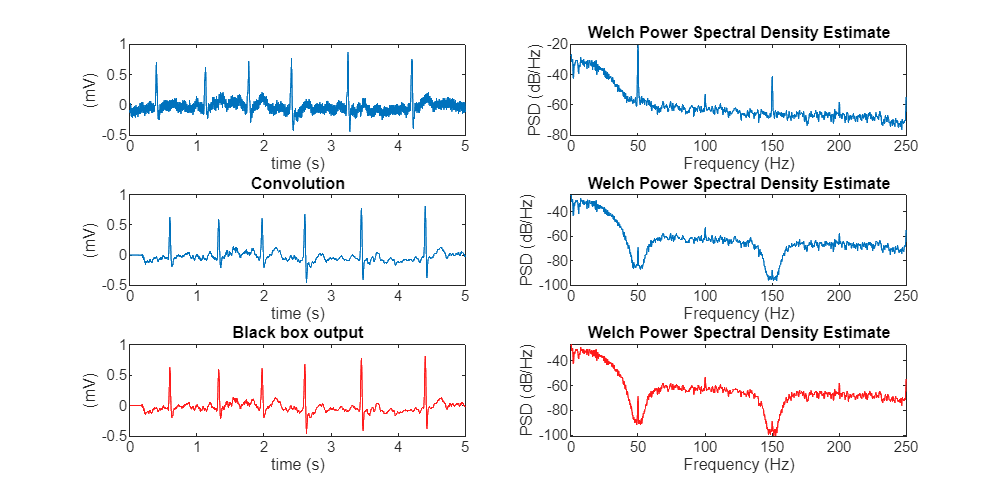

[PSD, F] = pwelch(ecg,[],[],[],fs);
PSD = 10*log10(PSD);

[PSDconv, Fconv] = pwelch(ecg_f,[],[],[],fs);
PSDconv = 10*log10(PSDconv);

[PSDbbox, Fbbox] = pwelch(ecg_bbox,[],[],[],fs);
PSDbbox = 10*log10(PSDbbox);

figure
set(gcf,'Position', [0 0 1000 500])
subplot(3,2,1)
plot(t,ecg)
xlim([0 5])
xlabel("time (s)")
ylabel("(mV)")

subplot(3,2,2)
plot(F,PSD)
xlabel("Frequency (Hz)")
ylabel("PSD (dB/Hz)")
title("Welch Power Spectral Density Estimate")

subplot(3,2,3)
plot(t_f,ecg_f)
xlim([0 5])
xlabel("time (s)")
ylabel("(mV)")
title("Convolution")

subplot(3,2,4)
plot(Fconv,PSDconv)
xlabel("Frequency (Hz)")
ylabel("PSD (dB/Hz)")
title("Welch Power Spectral Density Estimate")

subplot(3,2,5)
plot(t,ecg_bbox,Color='#ff1b1b')
xlim([0 5])
xlabel("time (s)")
ylabel("(mV)")
title("Black box output")

subplot(3,2,6)
plot(Fbbox,PSDbbox,Color='#ff1b1b')
xlabel("Frequency (Hz)")
ylabel("PSD (dB/Hz)")
title("Welch Power Spectral Density Estimate")

**Doplňte:**

**Co se stane se EKG signálem po konvoluci a po průchodem systémem?**

**dojde k potlačení pásem kolem 50 Hz a 150 Hz**

**Jaké je zpoždění systému v sekundách? **

Pomocí křížové korelace porovnejte EKG signál před konvolucí a po konvoluci. Výsledek si ověřte ručním odečtením např. na první R-špičce.

**Funkcí **`disp() `**vypište**:

`Systém zpozdí procházející signál o ... sekund.`

[Rxy, m] = xcorr(ecg,ecg_f);
tau = m/fs;
disp(["Systém zpozdí procházející signál o " + num2str(abs(tau(Rxy == max(Rxy)))) + " sekund"])

Systém zpozdí procházející signál o 0.2 sekund


## Bonus (+2 b)

Pro zadané signály a impulzní odezvy:

- vypočtěte konvoluci třemi způsoby (tj. doplnění nulami, cyklickou konvolucí a "zrcadlovou konvolucí"),

- nakreslete konvoluční automat,

- napište diferenční rovnici.

### Příklad výpočtu:

#### Konvoluce

Obecně, pro ruční výpočet konvoluce, je nejjednodušší otočit impulzní odezvu a následně postupovat s touto úpravou podobně jako u výpočtu korelace. Pokud bychom realizovaly výpočet dle pořadí vzorků vstupujících do systému, museli bychom otočit signál a následně i výstup ze systému (viz příklad s hadem v přednášce).

Jako příklad použijeme signál $\mathit{\mathbf{x}}=\left\lbrace 2,\;5,\;7,\;-1\right\rbrace$ a impulzní odezvu systému $\mathbf{h}=\left\lbrace 2,1\right\rbrace$.

Upravíme si tedy impulzní odezvu otočením v čase:


$$h^{\prime } \left\lbrack n\right\rbrack =h\left\lbrack -n\right\rbrack$$


tj. $\mathbf{h}=\left\lbrace 2,1\right\rbrace \to {\mathbf{h}}^{\prime } =\left\lbrace 1,\;2\right\rbrace$. 

Před samotným výpočtem potřebujeme určit, čím nahradíme vzorky v pozici, kde se signál $x\left\lbrack n\right\rbrack$ a otočená impulzní odezva $h^{\prime } \left\lbrack n\right\rbrack$ ještě nepřekrývají, tj. na začátku a na konci výpočtu. Ukážeme si tři způsoby:

- doplnění nulami,

- cyklická konvoluce,

- "zrcadlová konvoluce".

Při výpočtu **doplnění nulami:**

- Napíšeme před signál $M$nul, který odpovídá délce $K$ impulzní odezvy $h\left\lbrack n\right\rbrack ,M=K-1$ (pro konkrétní případ $\mathbf{h}=\left\lbrace 2,\;1\right\rbrace$ je $M=1$).

- Pro výpočet každého prvku konvoluce si vezmeme potřebný počet vzorků ze signálu (tj. $M+1$) a provedeme skalární součin se vzorky otočené impulzní odezvy.

- Pokud budeme porovnávat metody výpočtu mezi sebou (doplnění nulami, cyklicky, zrcadlením), vždy se budou rovnat ty prvky výsledku konvoluce, které jsou zcela pokryty původním signálem (značeno modře). Lišit se bude pouze výsledek konvoluce na okrajích, tedy pouze prvky na začátku a konci výstupu (černě tučně).

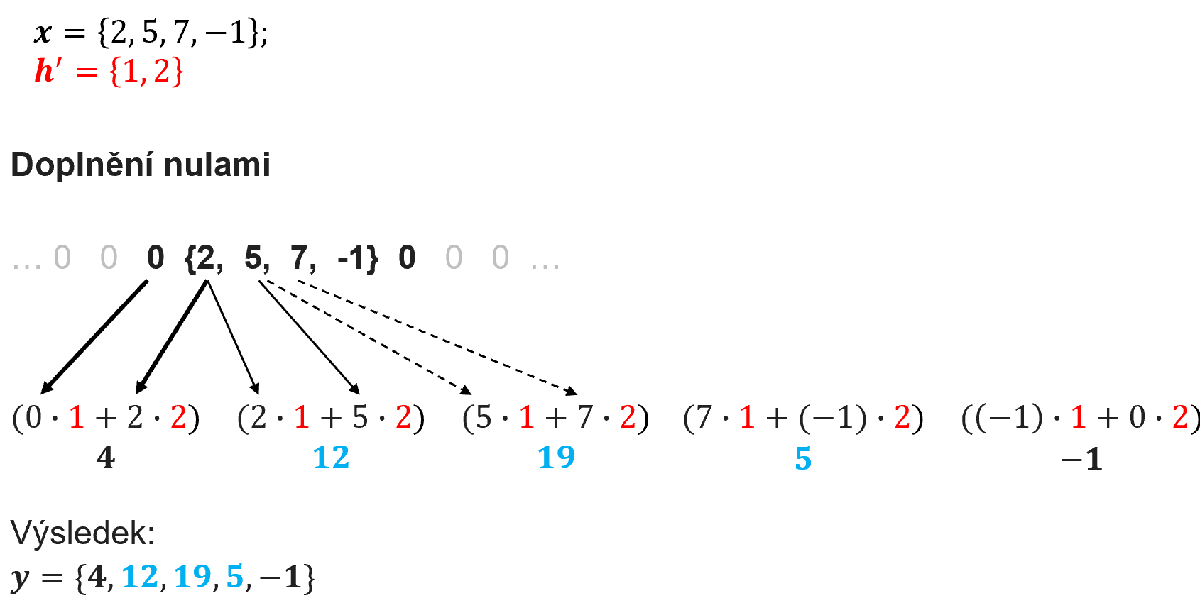

V závislosti na velikosti hodnoty počátečních (resp. koncových) vzorcích signálu, může na začátku (konci) výstupu po doplnění nulami vzniknout skok, který způsobí odezvu systému (v přednášce odezva na jednotkový skok). Místo doplnění nulami se může využít periodizace signálu a část před signálem lze nahradit jeho koncem a naopak - **cyklická konvoluce**. Místo nul opakujeme signál $x\left\lbrack n\right\rbrack$ tak, abychom na obou koncích měli o $M$ vzorků více pro výpočet. Pokud by tedy signál měl méně prvků než $M$, jednoduše signál opakuje znovu, aby finální počet vzorků odpovídal tomuto počtu. U výpočtu výstupu $y\left\lbrack n\right\rbrack$ dále postupuje stejně, jako u předešlé metody.

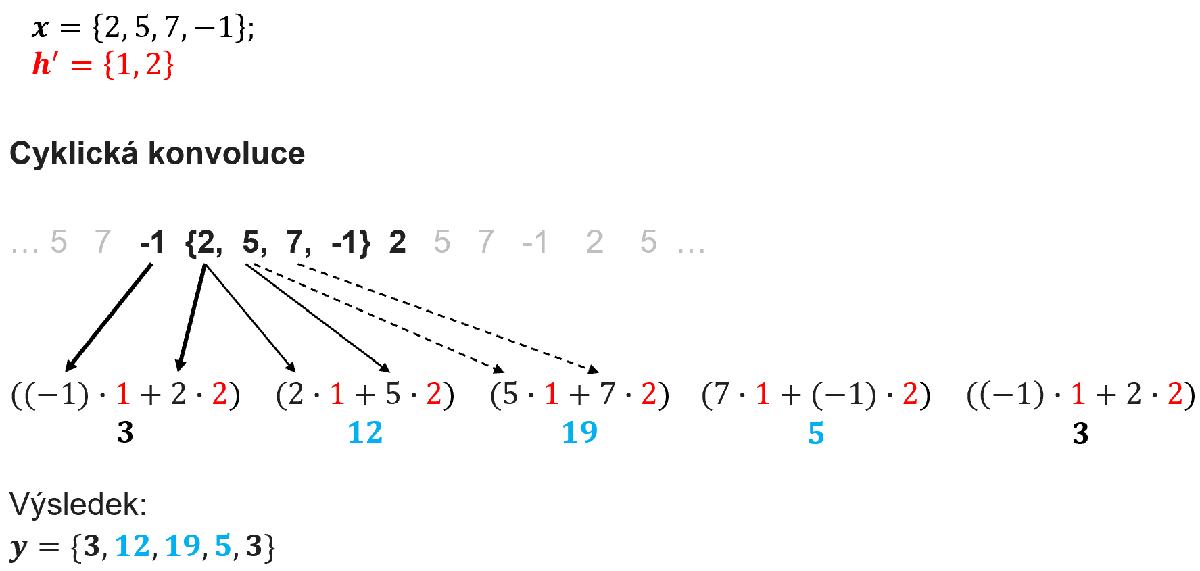

Při periodizaci ale narážíme na podobný problém, kdy neperiodické signály na svém konci a začátku na sebe nenavazují a vzniká také skok vedoucí k odezvě systému. Využijeme metody **"zrcadlové konvoluce"**. Signál střídavě časově otáčíme, tzn. dáváme k sobě začátky a konce signálu. Výpočet výstupu $y\left\lbrack n\right\rbrack$ vypadá opět stejně. Tím je zajištěno hladší napojení, nicméně za cenu zkreslení fázové složky.

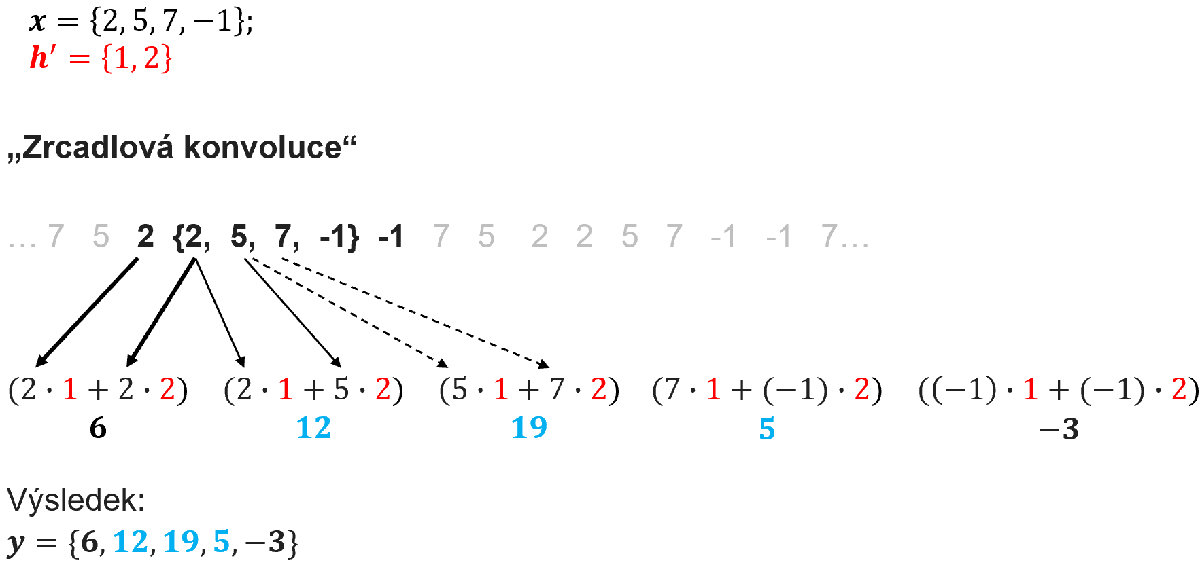

#### Diferenční rovnice

Diferenční rovnice předepisuje, jak bude vypadat konkrétní výstupní vzorek $y\left\lbrack n\right\rbrack$. Vzorky signálu $x\left\lbrack n\right\rbrack$ do systému nevstupují najednou, ale popořadě $\mathbf{x}=\left\lbrace x\left\lbrack n-0\right\rbrack ,\;x\left\lbrack n-1\right\rbrack ,\ldotp \ldotp \ldotp \;,\;x\left\lbrack N-1\right\rbrack \right\rbrace$. Lze tedy konvoluci rozepsat jako skalární násobení prvků impulzní odezvy se vzorky signálů, které do systému vstupují se zpožděním. 

Konvoluci lze tedy zapsat diferenční rovnicí následovně: 

$y\left\lbrack n\right\rbrack =\;h\left\lbrack 0\right\rbrack \cdot x\left\lbrack n\right\rbrack +h\left\lbrack 1\right\rbrack \cdot x\left\lbrack n-1\right\rbrack +\ldots+h\left\lbrack M\right\rbrack \cdot x\left\lbrack n-M\right\rbrack$.

Pro příklad výše $\mathbf{h}=\left\lbrace h\left\lbrack 0\right\rbrack ,\;h\left\lbrack 1\right\rbrack \right\rbrace =\left\lbrace 2,\;1\right\rbrace$,

$y\left\lbrack n\right\rbrack =2\cdot x\left\lbrack n\right\rbrack +1\cdot x\left\lbrack n-1\right\rbrack =2x\left\lbrack n\right\rbrack +x\left\lbrack n-1\right\rbrack$.

#### Konvoluční automat

Konvoluční automat (mřížková struktura) slouží jako schéma výpočtu diferenční rovnice. Automat můžeme vytvořit přímo z finitní impulzní odezvy:

- násobení konstantou 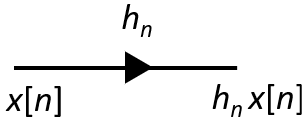,

- zpožďovací člen ,

- sčítačka  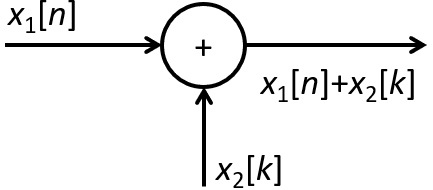.

Pro uvedený příklad $\mathit{\mathbf{h}}=\left\lbrace 2,1\right\rbrace$ překreslíme diferenční rovnici $y\left\lbrack n\right\rbrack =2x\left\lbrack n\right\rbrack +x\left\lbrack n-1\right\rbrack$:

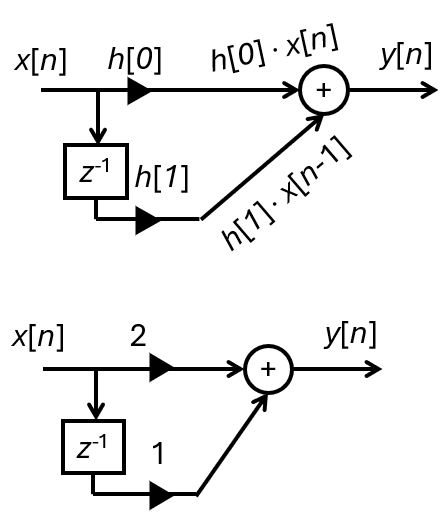

### **Zadání**

Alespoň pro dvě zadání:

- vypočtěte konvoluci třemi zmíněnými způsoby (doplnění nulami, cyklickou konvolucí a "zrcadlovou konvolucí"),

- napište diferenční rovnici,

- nakreslete konvoluční automat.

**1.**


$$\begin{array}{l}
{\mathbf{x}}_1 =\left\lbrace 1,\;5,\;-3,\;7,\;2,\;-1\right\rbrace \\
{\mathbf{h}}_1 =\left\lbrace 1,0\;,-1\right\rbrace 
\end{array}$$


**2.**


$$\begin{array}{l}
{\mathbf{x}}_2 =\left\lbrace 1,\;1,\;1,\;-7,\;3,\;5\right\rbrace \\
{\mathbf{h}}_2 =\left\lbrace 3,7\right\rbrace 
\end{array}$$


**3.**


$$\begin{array}{l}
{\mathbf{x}}_3 =\left\lbrace 1,\;2,\;3,\;4,\;5,\;5,\;5\right\rbrace \\
{\mathbf{h}}_3 =\left\lbrace 1,\;-1\right\rbrace 
\end{array}$$


**Řešení napište na papír a přiložte fotografii (nahoře na liště: insert -> image). Popř. můžete využít tabletu (či jiného zařízení) a přiložit výstřižek. Můžete také přinést na příští cvičení (cv7 FIR filtry) a konzultovat ústně.**